% Author:       Joe Zhang
% Email:        zhaoz@princeton.edu
% Date Started: 04/06/17
% Date Updated: 05/04/17
% 
% Function: duneGPS
%
% Input:  n/a
% Output: n/a
%
% Description: Plots GPR transects taken from the field trip onto a surface map of
%              the dune compiled by members of FRS135, Princeton University.
%
% BEGIN CODE
% Easting, northing, and elevation for points on the outline
% plot garmin gps data for dunes
% WPnumber, UTM Zone, UTM East, UTM North, Elevation
I = load('I11022015m.csv');
K = load('K11022015m.csv');
A = load('A11022015m.csv');
M = load('M11022015m.csv');
E =vertcat(I,K);

% plot of dune elevation model with line transects on top
figure (1)
ax1=subplot(1,2,1);
x = linspace(min(I(:,3)),max(I(:,3)),500);
y = linspace(min(I(:,4)),max(I(:,4)),500);
mineast=min(x);
minnorth=min(y);
x=x-mineast;
y=y-minnorth;
[xq yq] = meshgrid(x,y);
vq = griddata(E(:,3)-mineast,E(:,4)-minnorth,E(:,5),xq,yq);


% plots the two line transects analyzed in the presentation
[x1,y1,z1]=gatherVariables('FILE____032copy.csv');
[x2,y2,z2]=gatherVariables('FILE____036copy.csv');

% plot of every line taken by the GPR
[p1,q1,r1]=gatherVariables('FILE____002.csv');
[p2,q2,r2]=gatherVariables('FILE____003.csv');
[p3,q3,r3]=gatherVariables('FILE____004.csv');
[p4,q4,r4]=gatherVariables('FILE____005.csv');
[p5,q5,r5]=gatherVariables('FILE____006.csv');
[p6,q6,r6]=gatherVariables('FILE____007.csv');
[p7,q7,r7]=gatherVariables('FILE____008.csv');
[p8,q8,r8]=gatherVariables('FILE____009.csv');
[p9,q9,r9]=gatherVariables('FILE____010.csv');
[p10,q10,r10]=gatherVariables('FILE____011.csv');
[p11,q11,r11]=gatherVariables('FILE____012.csv');
[p12,q12,r12]=gatherVariables('FILE____013.csv');
[p13,q13,r13]=gatherVariables('FILE____015.csv');
[p14,q14,r14]=gatherVariables('FILE____016.csv');
[p15,q15,r15]=gatherVariables('FILE____017.csv');
[p16,q16,r16]=gatherVariables('FILE____018.csv');
[p17,q17,r17]=gatherVariables('FILE____019.csv');
[p18,q18,r18]=gatherVariables('FILE____020.csv');
[p19,q19,r19]=gatherVariables('FILE____021.csv');
[p20,q20,r20]=gatherVariables('FILE____022.csv');
[p21,q21,r21]=gatherVariables('FILE____023.csv');
[p22,q22,r22]=gatherVariables('FILE____024.csv');
[p23,q23,r23]=gatherVariables('FILE____025.csv');
[p24,q24,r24]=gatherVariables('FILE____026.csv');
[p25,q25,r25]=gatherVariables('FILE____027.csv');
[p26,q26,r26]=gatherVariables('FILE____028.csv');
[p27,q27,r27]=gatherVariables('FILE____029.csv');
[p28,q28,r28]=gatherVariables('FILE____030.csv');
[p29,q29,r29]=gatherVariables('FILE____031.csv');
[p30,q30,r30]=gatherVariables('FILE____032.csv');
[p31,q31,r31]=gatherVariables('FILE____033.csv');
[p32,q32,r32]=gatherVariables('FILE____034.csv');
[p33,q33,r33]=gatherVariables('FILE____035.csv');
[p34,q34,r34]=gatherVariables('FILE____036.csv');
[p35,q35,r35]=gatherVariables('FILE____037.csv');

% plots additional lines on top of the dune elevation model
hold on
contourf(ax1,xq,yq,vq)
cy1=1380; cy2=1480;
cx1=620; cx2=820;
plot([cx1 cx2 cx2 cx1 cx1],[cy1 cy1 cy2 cy2 cy1],'-y','LineWidth',3)
plot(ax1,p13-mineast,q13-minnorth,'g-','LineWidth',2)
plot(ax1,p14-mineast,q14-minnorth,'g-','LineWidth',2)
plot(ax1,p15-mineast,q15-minnorth,'g-','LineWidth',2)
plot(ax1,p16-mineast,q16-minnorth,'g-','LineWidth',2)
plot(ax1,p17-mineast,q17-minnorth,'g-','LineWidth',2)
plot(ax1,p18-mineast,q18-minnorth,'g-','LineWidth',2)
plot(ax1,p19-mineast,q19-minnorth,'g-','LineWidth',2)
plot(ax1,p20-mineast,q20-minnorth,'g-','LineWidth',2)
plot(ax1,p21-mineast,q21-minnorth,'g-','LineWidth',2)
plot(ax1,p22-mineast,q22-minnorth,'g-','LineWidth',2)
plot(ax1,p23-mineast,q23-minnorth,'g-','LineWidth',2)
plot(ax1,p24-mineast,q24-minnorth,'g-','LineWidth',2)
plot(ax1,p25-mineast,q25-minnorth,'g-','LineWidth',2)
plot(ax1,p26-mineast,q26-minnorth,'g-','LineWidth',2)
plot(ax1,p27-mineast,q27-minnorth,'g-','LineWidth',2)
plot(ax1,p28-mineast,q28-minnorth,'g-','LineWidth',2)
plot(ax1,p29-mineast,q29-minnorth,'g-','LineWidth',2)
plot(ax1,p30-mineast,q30-minnorth,'g-','LineWidth',2)
plot(ax1,p31-mineast,q31-minnorth,'g-','LineWidth',2)
plot(ax1,p32-mineast,q32-minnorth,'g-','LineWidth',2)
plot(ax1,p33-mineast,q33-minnorth,'g-','LineWidth',2)
plot(ax1,p34-mineast,q34-minnorth,'g-','LineWidth',2)
plot(ax1,p35-mineast,q35-minnorth,'g-','LineWidth',2)

% formats title, axes, and figure handles
txt1 = 'N';
txt2='E';
txt3='S';
txt4='W';
text(150,1760,txt1,'FontSize',15)
text(250,1680,txt2,'FontSize',15)
text(150,1600,txt3,'FontSize',15)
text(50,1680,txt4,'FontSize',15)
xlabel(sprintf('Easting from %d [m]',mineast),'FontSize',15);
ylabel(sprintf('Northing from %d [m]',minnorth),'FontSize',15);
tstring='Day 2 Grid Transects 15-37';
tl=title(tstring,'FontSize',18);
colormap(gray)
c=colorbar;
grid on
axis tight
hold off

% plots a zoomed-in image of the two transects analyzed in the final presentation
ax2=subplot(1,2,2);
axis([500 750 1400 1500]);
x = linspace(min(I(:,3)),max(I(:,3)),500);
y = linspace(min(I(:,4)),max(I(:,4)),500);
mineast=min(x);
minnorth=min(y);
x=x-mineast;
y=y-minnorth;
[xq yq] = meshgrid(x,y);
vq = griddata(E(:,3)-mineast,E(:,4)-minnorth,E(:,5),xq,yq);

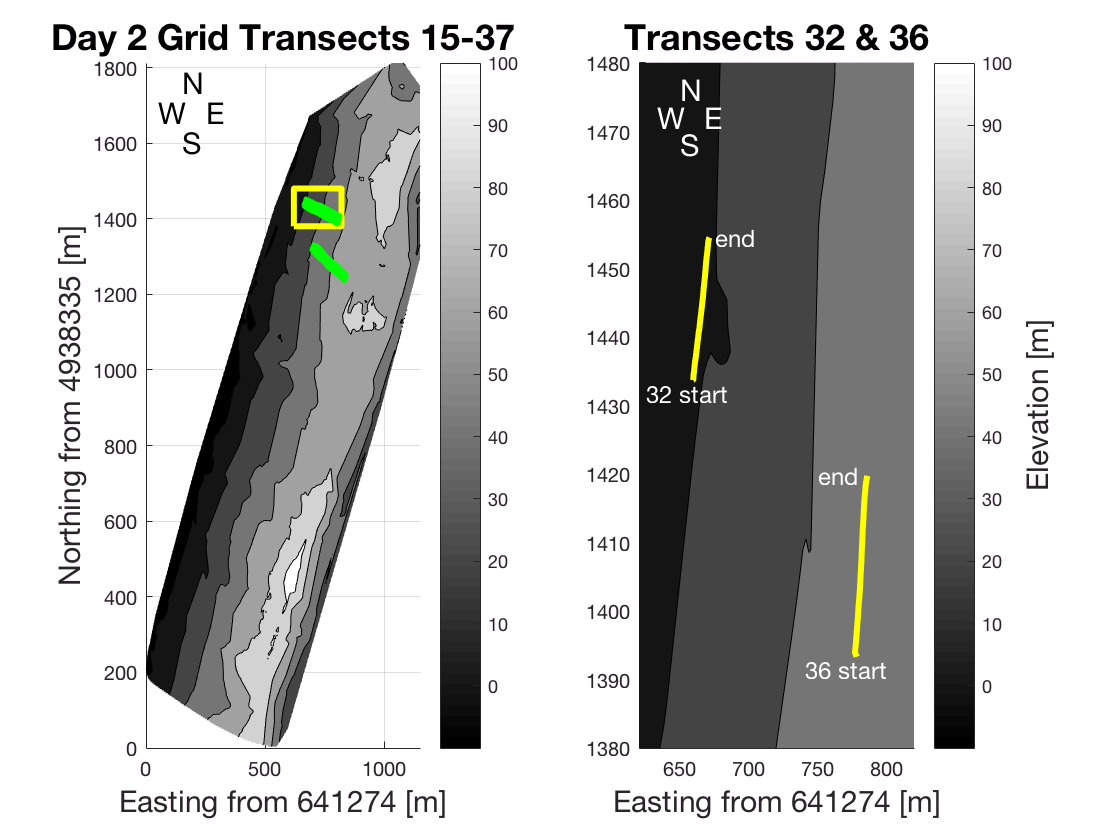

hold on
contourf(ax2,xq,yq,vq)
plot(ax2,x1-mineast,y1-minnorth,'y-','LineWidth',3)
hold on
plot(ax2,x2-mineast,y2-minnorth,'y-','LineWidth',3)
hold on

% general formatting of the right subplot
txt5 = 'N';
txt6='E';
txt7='S';
txt8='W';
text(650,1476,txt5,'FontSize',15,'Color','w')
text(667,1472,txt6,'FontSize',15,'Color','w')
text(650,1468,txt7,'FontSize',15,'Color','w')
text(633,1472,txt8,'FontSize',15,'Color','w')
txtline1='32 start';
text(x1(1)-mineast-34,y1(1)-minnorth-2,txtline1,'FontSize',12,'Color','w');
txtline12='end';
text(x1(length(x1))-mineast+4,y1(length(y1))-minnorth,txtline12,'FontSize',12,'Color','w');
txtline2='36 start';
text(x2(1)-mineast+2-40,y2(1)-minnorth-2,txtline2,'FontSize',12,'Color','w');
txtline22='end';
text(x2(length(x2))-mineast+2-38,y2(length(y2))-minnorth,txtline22,'FontSize',12,'Color','w');
xlabel(sprintf('Easting from %d [m]',mineast),'FontSize',15);
tstring='Transects 32 & 36';
tl=title(tstring,'FontSize',18);
colormap(gray)
c=colorbar;
grid on
ylabel(c,'Elevation [m]','FontSize',15)
axis tight
axis(ax1,[0 max(x) 0 max(y)]);
axis(ax2,[620 820 1380 1480]);
hold off


% saves the figure for printing
orient landscape
print('-dpdf','-bestfit',mfilename)
figdir='/Users/zhaozhang/frs124/GPR/code';
% issue the print command, which does the same as "save" it
print('-dpdf','-bestfit',fullfile(figdir,'gprTransects.pdf'))